**Robot movement in lidar scanned map using heuristics rolling window. Simply select an appropriate starting location.**

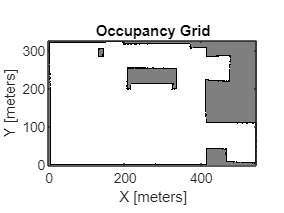


clear 
clc 

tic

% %Initialize ROS
% rosshutdown()
% rosinit("http://192.168.1.42:11311")
% 
% %Read published map from ROS 'map' topic
% sub = rossubscriber("/map",DataFormat="struct");
% msg = receive(sub);
% map = rosReadOccupancyGrid(msg);
% mat = occupancyMatrix(map); %an array containing the actual values of each grid in the occupancy map

map = occupancyMap(readmatrix("map builder.xlsx", "Sheet","100 park"));
show(map)


% clear
% clc
% image  = imread("1.pgm");
% imshow(image)
% imageNorm = double(image)/255;
% imageOccupancy = 1- imageNorm;
% map = occupancyMap(imageOccupancy,20);
% map = occupancyMap(map,10);
% % map = occupancyMap(imageOccupancy,2);
% show(map)
% 
% mat =  occupancyMatrix(map);

n = zeros(map.GridSize(1), map.GridSize(2)); %generate array to store neural activity values

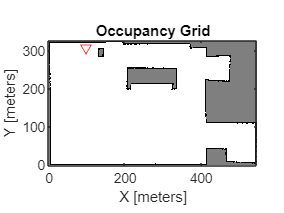

%initialize starting location
up_dir = '^r'; %indicator for robot heading direction on map
down_dir = 'vr'; %indicator for robot heading direction on map
left_dir = '<r'; 
right_dir = '>r';
hold on
pc = [20,100]; %starting grid location
xy = grid2world(map,pc); %convert starting grid location to xy coordinates
plot(xy(1), xy(2), down_dir) %plot starting location xy coordinates on map


% topic = rospublisher("/initialpose","geometry_msgs/PoseWithCovarianceStamped","DataFormat","struct");
% start = rosmessage("geometry_msgs/PoseWithCovarianceStamped","DataFormat","struct") 
% start.Pose.Pose.Position.X = xy(1);
% start.Pose.Pose.Position.Y = xy(2);
% start.Pose.Covariance;
% send(topic,start);

toc

Elapsed time is 1.947633 seconds.


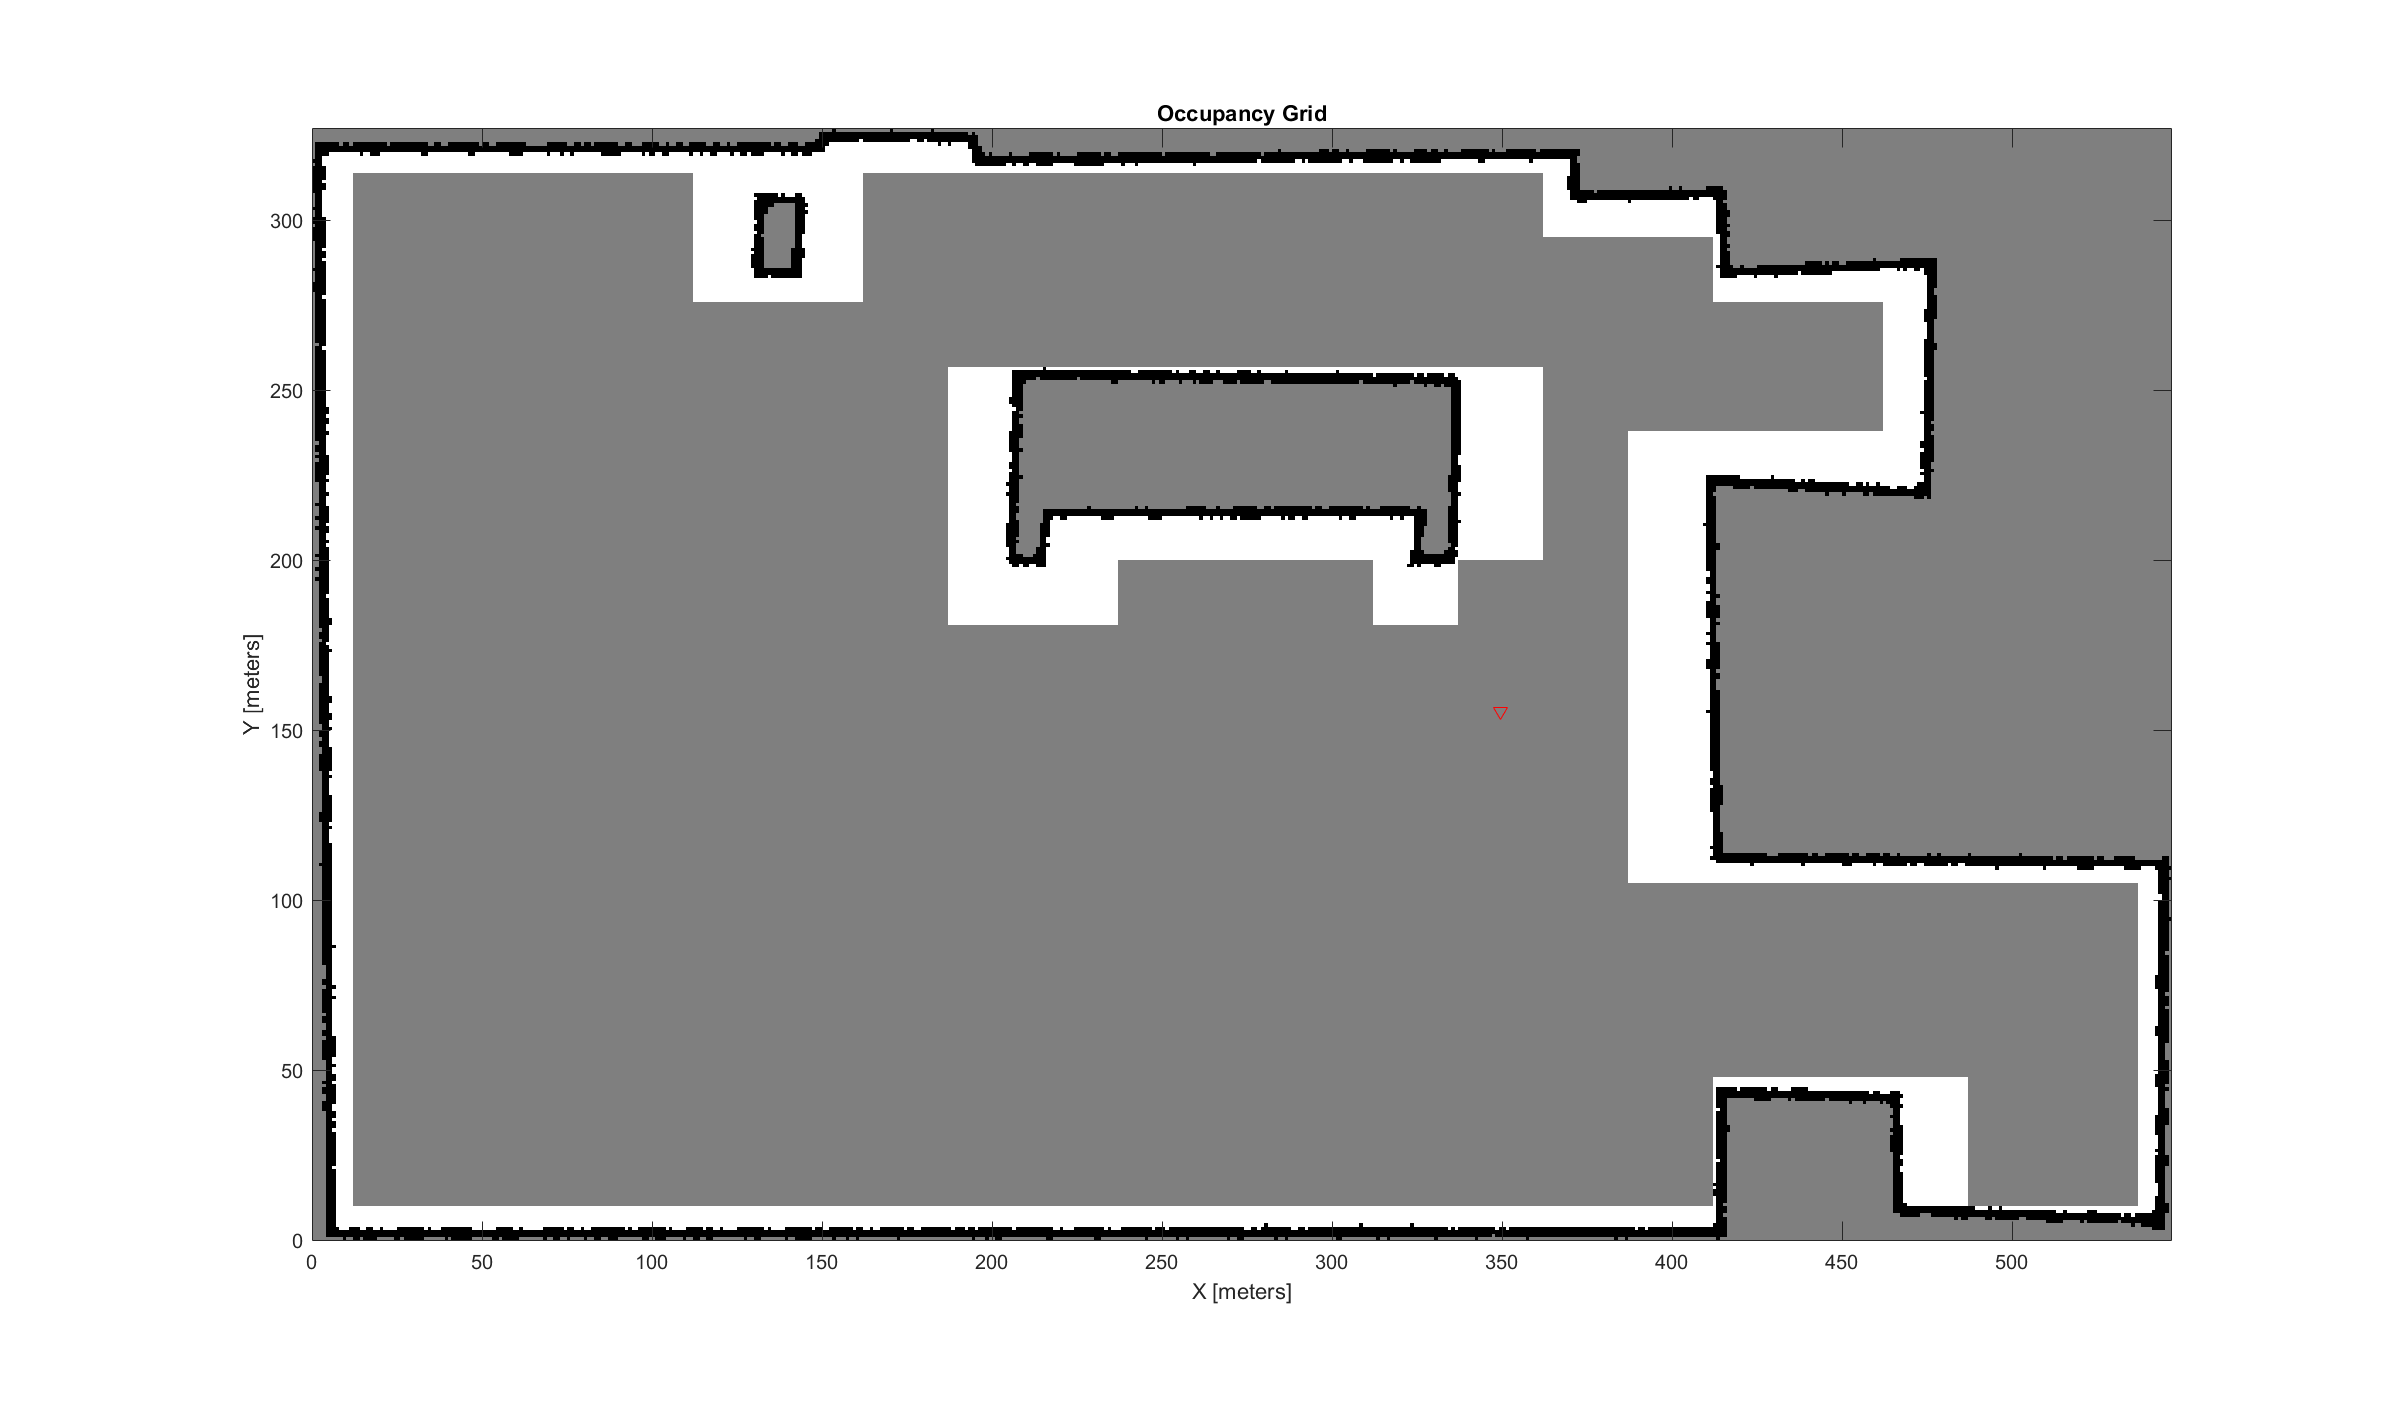

%pc = [15,18];
go = waitforbuttonpress; %CHANGEE!!!

tic
while go == 1 

%Building neural network of map

%find top left corner points in all directions
TL = [pc(1)-6, pc(2)-12];
NW_TL = [pc(1)-25, pc(2)-37];
N_TL = [pc(1)-25, pc(2)-12];
NE_TL = [pc(1)-25, pc(2)+13];
E_TL = [pc(1)-6, pc(2)+13];
SE_TL = [pc(1)+13, pc(2)+13];
S_TL = [pc(1)+13, pc(2)-12];
SW_TL = [pc(1)+13, pc(2)-37];
W_TL = [pc(1)-6, pc(2)-37];

%update status of current grid
for tl_j = TL(2):1:TL(2)+24
    for tl_i = TL(1):1:TL(1)+18
        setOccupancy(map,[tl_i, tl_j],0.5,'grid')
    end 
end 

%map = shadeCells(TL,map);
pause(0.005)
show(map)



%--------------------PATH SELECTION ALGORITHM-------------------------------%
%Heuristic sequence
%left -> bottom -> top -> right -> right bottom -> right top

%Find status of all possible next positions 
%[kNW,n] = directionStatus(NW_TL,map,n);
[kN,n] = directionStatus(N_TL,map,n);
[kNE,n] = directionStatus(NE_TL,map,n);
[kE,n] = directionStatus(E_TL,map,n);
[kSE,n] = directionStatus(SE_TL,map,n);
[kS,n] = directionStatus(S_TL,map,n);
%[kSW,n] = directionStatus(SW_TL,map,n);
[kW,n] = directionStatus(W_TL,map,n);

% modify check the status of all possible next locations
pn =[kW, kS, kN, kE, kSE, kNE]; %don't change order of this array

%check the status of all possible next locations
for value = 1:1:length(pn)
    if pn(value) < 0
        pn(value) = -1; %indicate cell is obstacle
    elseif pn(value) > 0.5
        pn(value) = 1; %indicate cell is uncovered
    elseif (pn(value) > 0) && (pn(value) < 0.5)  
        pn(value) = 0; %indicate cell is covered
    end
end


%modify deadlock event
if sum(pn==1) == 0 %check to for deadlock event
    [kSW,n] = directionStatus(SW_TL,map,n);
    [kNW,n] = directionStatus(NW_TL,map,n);
    [Kp,n] = directionStatus(TL,map,n);
    search = [Kp,kN,kNE,kE,kSE,kS,kSW,kW,kNW]; %search for uncovered location in closest neighbors using neural propagation
    switch max(search)
        case search(1)
            pc = moveNextDirection(TL,up_dir,map);
            %disp('north is next')
        case search(2)
            pc = moveNextDirection(N_TL,up_dir,map);
            %disp('north is next')
        case search(3)
            pc = moveNextDirection(NE_TL,up_dir,map);
            %disp('ne is next')
        case search(4)
            pc = moveNextDirection(E_TL,right_dir,map);
            %disp('east is next')
        case search(5)
            pc = moveNextDirection(SE_TL,down_dir,map);
            %disp('se is next')
        case search(6)
            pc = moveNextDirection(S_TL,down_dir,map);
            %disp('south is next')
        case search(7)
            pc = moveNextDirection(SW_TL,down_dir,map);
            %disp('sw is next')
        case search(8)
            pc = moveNextDirection(W_TL,left_dir,map);
            %disp('west is next')
        case search(9)
            pc = moveNextDirection(NW_TL,up_dir,map);
            %disp('nw is next')
    end

     %once uncovered location is found revert back to heuristic path selection
else %continue on with heuristic path selection
    switch max(pn)
        case pn(1)
            pc = moveNextDirection(W_TL,left_dir,map);
            %disp('west is next')
        case pn(2)
            pc = moveNextDirection(S_TL,down_dir,map);
            %disp('south is next')
        case pn(3)
            pc = moveNextDirection(N_TL,up_dir,map);
            %disp('north is next')
        case pn(4)
            pc = moveNextDirection(E_TL,right_dir,map);
            %disp('east is next')
        case pn(5)
            pc = moveNextDirection(SE_TL,down_dir,map);
            %disp('se is next')
        case pn(6)
            pc = moveNextDirection(NE_TL,up_dir,map);
            %disp('ne is next')      
    end
end

%mat = occupancyMatrix(map); %update grid values of the map 
%mesh(n)

% Stop condition 
%check if map/environment is completely covered and end operation 
if sum(n>=0.5, 'all') == 0
    go = 0;
    break
end 

end

toc

Elapsed time is 1543.962790 seconds.


function [y,n] = directionStatus(x,map,n_mat)
%Use a try block to iterate through and calcuate n-values for all cells eqauting to the size of bot in specified direction
    try
        n = n_mat;
        for j = x(2):1:x(2)+24 %{Reference; j is cols (goes left to right)}
            for i = x(1)-1:1:x(1)+18  %{Reference; i is rows (goes up and down)}
                status = checkOccupancy(map, [i,j], "grid"); %check status of current grid position
                %convert grid values to 'I' values
                if status == 1
                    i = x(1) + 6;
                    j = x(2) + 12;
                    I = -100; 
                    calculateNeuralActivity
                    return
                end 
            end 
        end 

        %if no cell in the group is an obstacle, check the status of cell where COG is located and use it's n-value for the specified direction
        i = x(1)+6;
        j = x(2)+12;
        %ab = grid2world(map, [i,j]);
        status = checkOccupancy(map, [i,j], "grid");
        switch status
            case -1 %uncovered
                I = 0;
                calculateNeuralActivity
                return
            case 0 %covered 
                I = 100;
                calculateNeuralActivity
                return
        end 
    
    catch %Catch "index out of bounds" errors and assign n-value of specified direction as obstacle (-0.6)
        y = -0.6;
        return
    end %for the try/catch

    function calculateNeuralActivity

        I_plus = max([I 0]);
        I_neg = max([-1*I 0]);
        
        %check neural activity level of neighboring neurons, evaluate using ReLu, and calcuate euclidean distance
        %input the correct displacement values for the COG of the neighboring direction
        [North, dNorth] = ReLu(-19,0); %n(i, j-1)
        [South, dSouth] = ReLu(19,0); %n(i+1, j)
        [West, dWest] = ReLu(0,-25); %n(i, j-1)
        [East, dEast] = ReLu(0,25); %n(i, j+1)
        [NW, dNW] = ReLu(-19,-25); %n(i-1, j-1)
        [NE, dNE] = ReLu(-19,25); %n(i-1, j+1)
        [SW, dSW] = ReLu(19,-25); %n(i+1, j-1)
        [SE, dSE] = ReLu(19,25); %n(i+1, j+1)
        
        
        %store evaluated neural activity values for neighboring neurons (8x1 matrix/array)
        xplus = [North, South, West, East, NW, NE, SW, SE];
        
        %store euclidean distances (1x8 matrix/array)
        wij = [dNorth; dSouth; dWest; dEast; dNW; dNE; dSW; dSE];
        
        %calculate the weight
        weight = xplus * wij; % Matrix operation calculating for the weight (order of operation should not be changed)
        
        %set variables
        A = 80;
        B = 1;
        D = 1;
        %define & evaluate equation using ODE solver 
        eqn = @(t,Xi) ((-A*Xi) + (B-Xi)*(I_plus + weight) - (D+Xi)*I_neg);
        [t,Xi] = ode45(eqn, [0:1], n(i,j));
        n(i,j) = Xi(end);
        y = n(i,j);

    end

    % function to check neural activity level of neighboring neurons, evaluate using ReLu, and calcuate euclidean distance
    function [dir, dir_dist] = ReLu(RowDisp,ColDisp)
        %input the correct displacement values for the COG of the neighboring direction 
        ab = grid2world(map, [i,j]); %current grid position for neural activity calculation
        try
            dir = max([n(i + RowDisp, i + ColDisp) 0]); 
            dir_dist = 0.7/((norm(ab - grid2world(map, [i + RowDisp, j + ColDisp]))));
        catch
            dir = 0;
            dir_dist = 0;
        end 
    end 
    
end %for the function


function pc = moveNextDirection(pTL,heading,map)
    pc = [pTL(1)+6, pTL(2)+12];
    gpc = grid2world(map, pc);

%     topic = rospublisher("/move_base_simple/goal","geometry_msgs/PoseStamped","DataFormat","struct");
%     goal = rosmessage("geometry_msgs/PoseStamped","DataFormat","struct");
%     goal.Pose.Position.X = gpc(1);
%     goal.Pose.Position.Y = gpc(2);
%%%%% Yaw: Rotate around the Y-axis (up-down axis)%%%%%
%%%%% roll - Z, pitch - X, yaw - Y (eul2quat sequence: YXZ) %%%%%
%     goal.Pose.Orientation.X = str2double(heading(1));
%     goal.Pose.Orientation.Y = str2double(heading(2));
%     goal.Pose.Orientation.Z = str2double(heading(3));
%     goal.Pose.Orientation.W = str2double(heading(4));
%     send(topic,goal);

    plot(gpc(1), gpc(2),heading)
    
    %shadeCells(pTL,map)
end 
    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% function occ_map = shadeCells(corner,map)
%     for tl_j = corner(2):1:corner(2)+24
%         for tl_i = corner(1):1:corner(1)+18
%             setOccupancy(map,[tl_i, tl_j],0.5,'grid')
%         end 
%     end 
%     occ_map = map;
% end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Check 'status' of cells in size of robot area
%If a cell is flagged as an obstacle, break out of loop and assign cell direction n=-0.6 

%         if status == -1 %uncovered 
%             I = 0;
%         elseif status == 0 %covered 
%             I = 100;
%         else %obstacle
%             I = -100; 
%         end
%        
%         y = n(x(1)+6,x(2)+12);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% function [dir, dir_dist] = ReLu(Row,Col,RowDisp,ColDisp,map,n)
%     try
%         dir = max([n(Row + RowDisp, Col + ColDisp) 0]); 
%         dir_dist = 0.7/((norm(ab - grid2world(map, [Row + RowDisp, Col + ColDisp]))));
%     catch
%         dir = 0;
%         dir_dist = 0;
%     end 
% end 


%ROS integration
%Threading to accomodate multiple robots 
%Incorporate robot shift on intital encounter of an obstacle 
%Scale robot size and and program operation based on resolution of map